cd('C:\Users\PC\Desktop\3081\Content-based-Image-Retrieval')

%CIFAR100
% rootFolder = 'cifar-100-matlab\CIFAR-100\TEST';
% categories = {'cup','dinosaur','forest','hamster'};

%COREL80
rootFolder = 'CorelDB';
categories = {'art_antiques','obj_car','sc_sunset','wl_buttrfly','bld_sculpt'};

imds = imageDatastore(fullfile(rootFolder, categories), 'LabelSource', 'foldernames');
imagesPerClass = 100;
[trainingSet, ~] = splitEachLabel(imds, imagesPerClass, 'randomize'); 

% featureSet = [];
ref = [];
numImages = numel(trainingSet.Files);
featureSet = zeros(numImages, 64, "double"); % glcm + hog features

% preprocess the images in the dataset and collect:
% - their SIFT features into the featureSet matrix
% - their original image ID into the ref vector
for i = 1 : numImages
    I = im2gray(readimage(trainingSet,i));
    I = imresize(I, [120 120]); % can try without this
    
    % corners
    % no_corners = getnoofconers (I);

    % GLCM
    glcm = graycomatrix(I, 'NumLevels', 8, 'GrayLimits', []);
    
    % HOG
%     [hog_4x4, vis4x4] = extractHOGFeatures(I, 'CellSize', [4 4]);

%     featureSet(i, :) = cat(2, reshape(glcm,[1,64]), hog_4x4); 
    featureSet(i, :) = reshape(glcm,[1,64]); 

end

featureSet = featureSet.'

featureSet = 	1.0e+04 *

    0.0207    0.1522    0.0689    0.0328    0.0343    0.1590    0.1080    0.2195    0.1341    0.1788    0.1749    0.1793    0.0311    0.1642    0.0474    0.0401    0.0063    0.1489    0.0119    0.1494    0.0255    0.0095    0.4693    0.0305    0.0138    0.0757    0.1640    0.0654    0.0076    0.1834    0.0176    0.0401    0.0120    0.0249    0.0774    0.3676    0.0920    0.0632    0.0222    0.0121    0.1800    0.0341    0.0083    0.0395    0.0682    0.0385    0.0615    0.0112    0.0048    0.0128
    0.0063    0.0303    0.0391    0.0163    0.0066    0.0249    0.0131    0.0521    0.0245    0.0605    0.0207    0.0310    0.0070    0.0212    0.0192    0.0087    0.0024    0.0241    0.0030    0.0257    0.0116    0.0021    0.0341    0.0117    0.0092    0.0330    0.0410    0.0082    0.0029    0.0360    0.0058    0.0105    0.0071    0.0150    0.0264    0.0281    0.0157    0.0315    0.0167    0.0047    0.0094    0.0059    0.0041    0.0205    0.0163    0.0070    0.0118    

% construct LSH hash tables for featureSet
cd('C:\Users\PC\Desktop\3081\Content-based-Image-Retrieval\vLSH')

% Tune hyperparameters
% Q = 144;  % # of queries
K = 32;   % # of nearest neighbors to search for each query
L = 10;   % # of tables
M = 10;   % # of dimensions at projection space
W = 1000; % bucket width
T = 10;   % # of additional probing bins

% Construct index tables
lshStruct = lshConstruct(featureSet, L, M, W);

Creating table 1/10
	Projecting data...
	500 buckets
	min / max size: 1 / 1
	mean / median: 1 / 1
Creating table 2/10
	Projecting data...
	500 buckets
	min / max size: 1 / 1
	mean / median: 1 / 1
Creating table 3/10
	Projecting data...
	500 buckets
	min / max size: 1 / 1
	mean / median: 1 / 1
Creating table 4/10
	Projecting data...
	500 buckets
	min / max size: 1 / 1
	mean / median: 1 / 1
Creating table 5/10
	Projecting data...
	500 buckets
	min / max size: 1 / 1
	mean / median: 1 / 1
Creating table 6/10
	Projecting data...
	500 buckets
	min / max size: 1 / 1
	mean / median: 1 / 1
Creating table 7/10
	Projecting data...
	500 buckets
	min / max size: 1 / 1
	mean / median: 1 / 1
Creating table 8/10
	Projecting data...
	500 buckets
	min / max size: 1 / 1
	mean / median: 1 / 1
Creating table 9/10
	Projecting data...
	500 buckets
	min / max size: 1 / 1
	mean / median: 1 / 1
Creating table 10/10
	Projecting data...
	500 buckets
	min / max size: 1 / 1
	mean / median: 1 / 1
Total time: 0.20831

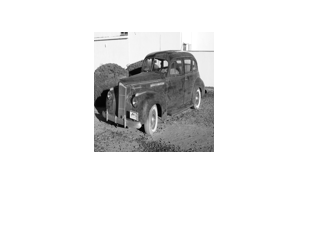

% query an input image
I = imread("car1.jpg");
I = imresize(im2gray(I), [120 120]);
figure, imshow(I); 


% corners
% no_corners = getnoofconers (I);

% GLCM
glcm = graycomatrix(I, 'NumLevels', 8, 'GrayLimits', []);

% HOG
% [hog_4x4, vis4x4] = extractHOGFeatures(I, 'CellSize', [4 4]);

% queryFeatures = cat(2, reshape(glcm,[1,64]), hog_4x4); 
queryFeatures = reshape(glcm,[1,64]); 
queryFeatures = queryFeatures.';

% [idsMULTIPROBE, cand_sizeMULTIPROBE, binsFound_ratiosMULTIPROBE] = lshSearch(featureSet(:, 1:Q), featureSet, lshStruct, K, T);
[query_ids, cand_sizeMULTIPROBE, binsFound_ratiosMULTIPROBE] = lshSearch(featureSet(:, 1), featureSet, lshStruct, K, T);

Retrieving candidates from table 1


Error using mat2cell (line 89)
Input arguments, D1 through D2, must sum to each dimension of the input matrix size, [0  1].

Error in lshSearchTable (line 50)
searchBinsQueryIndices = cellfun(@find, mat2cell(searchBinsQueriesMatrix, Q, ones(1, SB)), 'UniformOutput', false);

Error in 

% aggregate and weight the image features by their ranks 
uniqImageIds = unique(query_ids);
N = numel(uniqImageIds);
weights = zeros(N,1);
fib = zeros(1, K); fib(K-1) = 1;
for i = K-2:-1:1
   fib(i) = fib(i+1)+fib(i+2);
end

for k = 1 : N
    weights(k) = sum(sum(query_ids == uniqImageIds(k))); % unranked weighting of NNs
    % ranked weighting of NNs
%   weights(k) = sum((K + (0 : K - 1) * -1) * (oriImages == uniqImageIds(k)));  % linear
%   weights(k) = sum(flip(exp(1 : K)) * (oriImages == uniqImageIds(k))); % exponential
%   weights(k) = sum(fib * (oriImages == uniqImageIds(k))); % fibonacci
end

ranks = sortrows([weights uniqImageIds], 1, 'descend');


% display top 20 the matching images
for pic = 1 : min(20, length(ranks))
    if ranks(pic,2)>0
        % plot original image
        I = readimage(trainingSet, ranks(pic, 2));
        I = imresize(I, [120 120]);
        figure, imshow(I); 
    end
end

